# Exercise 19 Chapter 5

Fitting data with periodic functions $T(t) = a_0 + a_1sin(t) + a_2 cos(t)$

Instead of hours we will use minuts, since it will be easier to process. 

clear all
close all

% The data to fit 
hora = [8*60+14, 7*60+49, 7*60+2, 6*60+6, 5*60+13, 4*60+36, 4*60+29, 4*60+51, 5*60 + 27, 6*60+3, 6*60+42, 7*60+24, 8*60+2];
dia = [1 29 57 85 113 141 169 197 225 253 281 309 337];
dia = 2*pi*dia/max(dia);

plot(dia, hora, '--k','LineWidth', 0.3)
title('Hora de sortida del sol', 'Interpreter','latex')
xlabel("Dia de l'any", 'Interpreter','latex')
ylabel("Minut de sortida del sol",'Interpreter','latex')
hold on

% Data fit with T(t) = a0 + a1 sin(t) + a2 cos(t) = V(t)*a
sint = sin(dia);
cost = cos(dia);

V = [ones(size(dia)); sint; cost]'      % matrix such that Hora = V*a

V =    1.000000000000000   0.018643386619389   0.999826196963932
   1.000000000000000   0.514727291096737   0.857353961791870
   1.000000000000000   0.873689091856081   0.486484707644235
   1.000000000000000   0.999902234553183  -0.013982894391036
   1.000000000000000   0.859743843652124  -0.510725487226036
   1.000000000000000   0.490551775036032  -0.871412047202125
   1.000000000000000  -0.009322098370745  -0.999956548296958
   1.000000000000000  -0.506712587348964  -0.862115046743831
   1.000000000000000  -0.869116070276587  -0.494608184714913
   1.000000000000000  -0.999989137015237   0.004661099818829


a = V\hora'

a = 	1.0e+02 *

   3.705755573545563
   0.032280070598733
   1.041316939859847


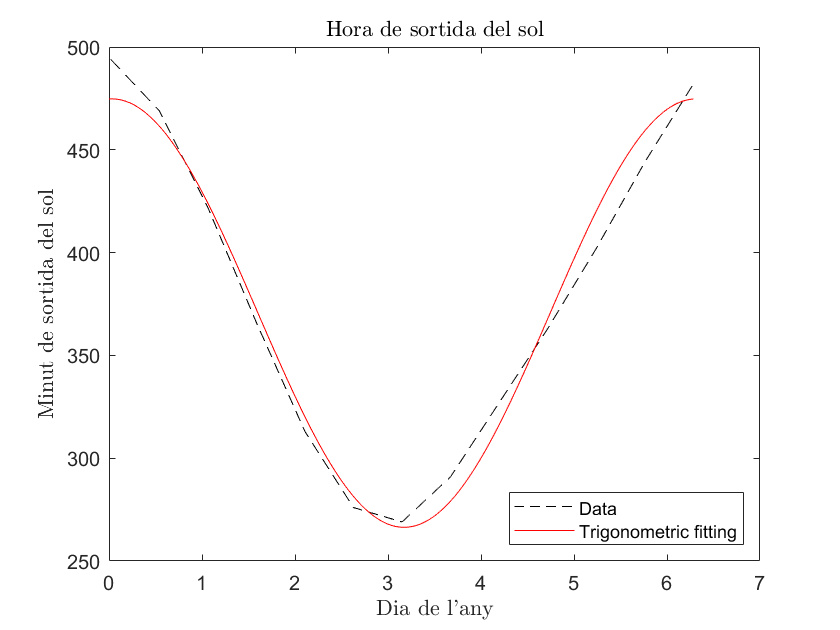


% Mesh
mesh = linspace(0,2*pi, 365);
sint_mesh = sin(mesh);
cost_mesh = cos(mesh);

V_mesh = [ones(size(mesh)); sint_mesh; cost_mesh]';     %vandermonde to evaluate the mesh
expected_hour = V_mesh*a;

plot(mesh, expected_hour, '-r')
legend('Data','Trigonometric fitting', "Location",'southeast')


% Error :)
e = sum((hora - a(1) - a(2)*sint - a(3)*cost).^2)

e =      1.450922512688513e+03
